# Train SVM Classifiers Using a Gaussian Kernel

This example shows how to generate a nonlinear classifier with Gaussian kernel function. First, generate one class of points inside the unit disk in two dimensions, and another class of points in the annulus from radius 1 to radius 2. Then, generates a classifier based on the data with the Gaussian radial basis function kernel. The default linear classifier is obviously unsuitable for this problem, since the model is circularly symmetric. Set the box constraint parameter to `Inf` to make a strict classification, meaning no misclassified training points. Other kernel functions might not work with this strict box constraint, since they might be unable to provide a strict classification. Even though the rbf classifier can separate the classes, the result can be overtrained.

Generate 100 points uniformly distributed in the unit disk. To do so, generate a radius *r* as the square root of a uniform random variable, generate an angle *t* uniformly in (0, $2\pi$), and put the point at (*r* cos(*t*), *r* sin(*t*)).

rng(1); % For reproducibility
r = sqrt(rand(100,1)); % Radius
t = 2*pi*rand(100,1);  % Angle
data1 = [r.*cos(t), r.*sin(t)]; % Points

Generate 100 points uniformly distributed in the annulus. The radius is again proportional to a square root, this time a square root of the uniform distribution from 1 through 4.

r2 = sqrt(3*rand(100,1)+1); % Radius
t2 = 2*pi*rand(100,1);      % Angle
data2 = [r2.*cos(t2), r2.*sin(t2)]; % points

Plot the points, and plot circles of radii 1 and 2 for comparison.

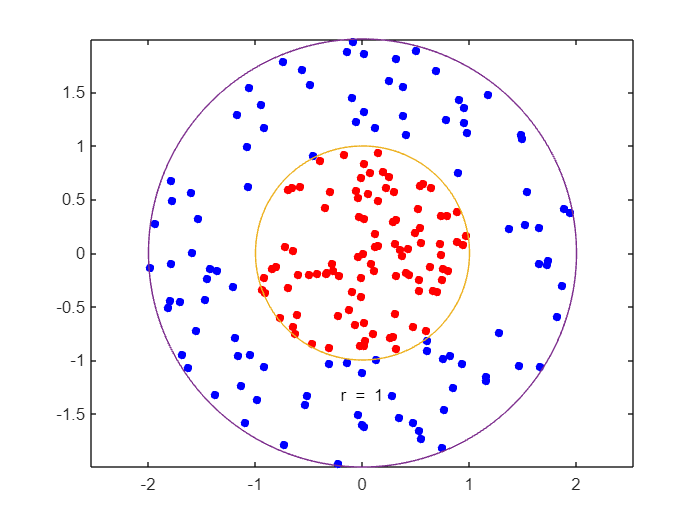

figure;
plot(data1(:,1),data1(:,2),'r.','MarkerSize',15)
hold on
plot(data2(:,1),data2(:,2),'b.','MarkerSize',15)
ezpolar(@(x)1);ezpolar(@(x)2);
axis equal
hold off

Put the data in one matrix, and make a vector of classifications.

data3 = [data1;data2];
theclass = ones(200,1);
theclass(1:100) = -1;

Train an SVM classifier with `KernelFunction` set to `'rbf'` and `BoxConstraint` set to `Inf`. Plot the decision boundary and flag the support vectors.

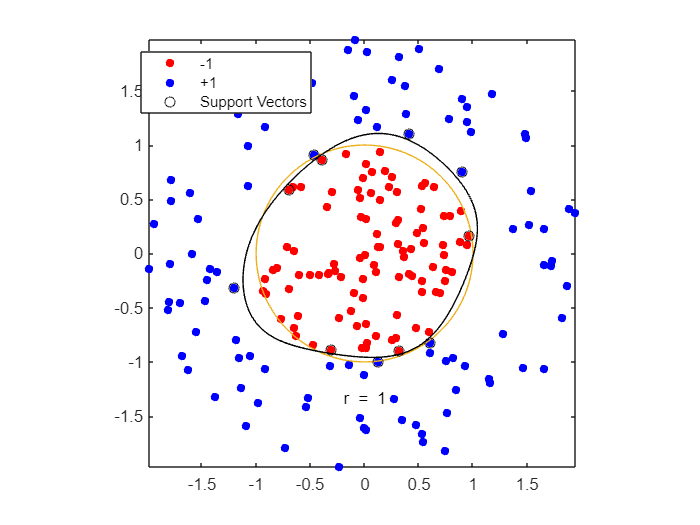

%Train the SVM Classifier
cl = fitcsvm(data3,theclass,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% Predict scores over the grid
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(data3(:,1)):d:max(data3(:,1)),...
    min(data3(:,2)):d:max(data3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);

% Plot the data and the decision boundary
figure;
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(data3(cl.IsSupportVector,1),data3(cl.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off

`fitcsvm` generates a classifier that is close to a circle of radius 1. The difference is due to the random training data.

Training with the default parameters makes a more nearly circular classification boundary, but one that misclassifies some training data. Also, the default value of `BoxConstraint` is `1`, and, therefore, there are more support vectors.

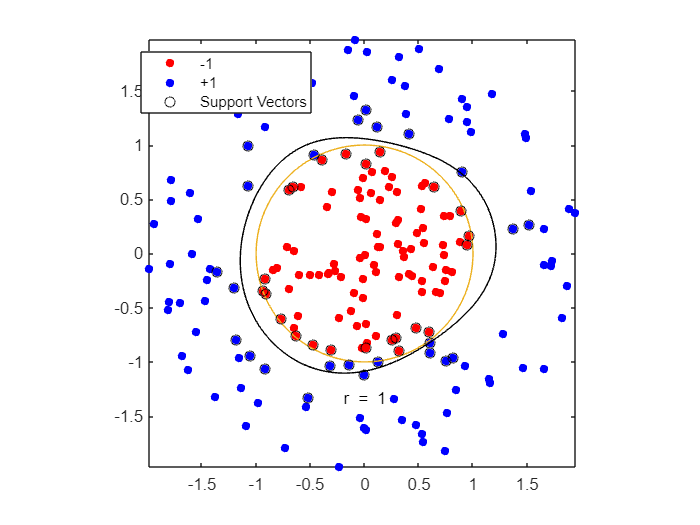

cl2 = fitcsvm(data3,theclass,'KernelFunction','rbf');
[~,scores2] = predict(cl2,xGrid);

figure;
h(1:2) = gscatter(data3(:,1),data3(:,2),theclass,'rb','.');
hold on
ezpolar(@(x)1);
h(3) = plot(data3(cl2.IsSupportVector,1),data3(cl2.IsSupportVector,2),'ko');
contour(x1Grid,x2Grid,reshape(scores2(:,2),size(x1Grid)),[0 0],'k');
legend(h,{'-1','+1','Support Vectors'});
axis equal
hold off